## Ufuksal Koordinat Sistemi

% Küreyi Oluştur
% [X, Y, Z] = sphere(50);
% R = 90;
% X = R*X;
% Y = R*Y;
% Z = R*Z;
% 
% surf(X,Y,Z,EdgeColor="none",FaceColor="interp",FaceAlpha=0.3)
% axis equal
% colormap autumn


% create_sphere




% Ufuk Çizgisini Ayarla
% theta = linspace(0,2*pi,200);
% 
% 
% zval = R*sind(0);
% r = R*cosd(0);
% x = r*cos(theta);
% y = r*sin(theta);
% z = zval * ones(size(theta));
% 
% hold on
% plot3(x,y,z,Color=[169/255 169/255 169/255],LineWidth=0.01)



% Eksenleri Ayarla
% alt_ticks = -90:30:90;
% z_ticks = 90 * sind(alt_ticks);
% set(gca, 'ZTick', z_ticks, 'ZTickLabel', alt_ticks);
% set(gca, 'XTick', [], 'YTick', []);
% 
% axis([-100 100 -100 100 -100 100])



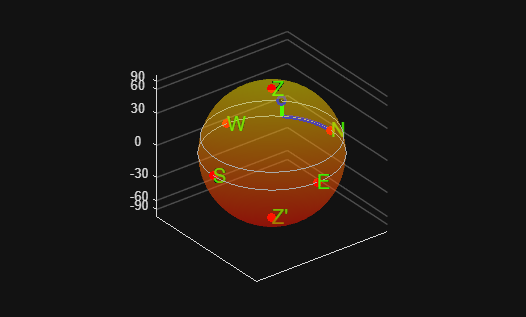

% Cismi Belirle
a_One = 15;
AW_One = 45;


% object_on_sphere(a_One,AW_One)

horizontal_celestial_sphere(a_One,AW_One)


% [x_One y_One z_One] = spherical_to_cartesian(a_One,AW_One);
% hold on
% plot3(x_One,y_One,z_One,"bo",MarkerFaceColor="auto",LineWidth=2)

% Kardinal Noktaları Belirle
% zenith = [0 0 R];
% nadir = [0 0 -R];
% north = [R 0 0];
% south = [-R 0 0];
% east = [0 -R 0];
% west = [0 R 0];
% plot3(zenith(1),zenith(2),zenith(3),"ro",MarkerFaceColor="r")
% plot3(nadir(1), nadir(2), nadir(3),"ro",MarkerFaceColor="r")
% plot3(north(1),north(2),north(3),"ro",MarkerFaceColor="r")
% plot3(south(1),south(2),south(3),"ro",MarkerFaceColor="r")

% text(zenith(1),zenith(2),zenith(3),"Z","FontSize",15,"Color",[71/255 233/255 1/255])
% text(nadir(1),nadir(2),nadir(3),"Z'","FontSize",15,"Color",[71/255 233/255 1/255])
% text(north(1),north(2),north(3),"N","FontSize",15,"Color",[71/255 233/255 1/255])
% text(south(1),south(2),south(3),"S","FontSize",15,"Color",[71/255 233/255 1/255])

% plot_cardinals(zenith,"Z")
% plot_cardinals(nadir,"Z'")
% plot_cardinals(north,"N")
% plot_cardinals(south,"S")
% plot_cardinals(east,"E")
% plot_cardinals(west,"W")

% labels = [zenith;nadir;north;south;east;west];
% names = ["Z";"Z'";"N";"S";"E";"W"];
% for i = 1:length(labels)
%     plot_cardinals(labels(i,:), names(i));
% end

% İzdüşümleri Çiz
% altproj = linspace(0,a_One,50);
% [altproj_x altproj_y altproj_z] = spherical_to_cartesian(R,altproj,AW_One);
% azproj = linspace(0,AW_One,50);
% [azproj_x azproj_y azproj_z] = spherical_to_cartesian(R,0,azproj);
% 
% plot3(altproj_x,altproj_y,altproj_z,"g-",LineWidth=3)
% for alt = a_One
%     zval = R*sind(alt);
%     r = R*cosd(alt);
%     x = r*cos(theta);
%     y = r*sin(theta);
%     z = zval * ones(size(theta));
% 
%     hold on
%     plot3(x,y,z,Color=[169/255 169/255 169/255],LineWidth=0.01)
% 
% end
% plot3(azproj_x,azproj_y,azproj_z,"b-",LineWidth=3)

% plot_projections(a_One,AW_One)

Koordinat Dönüşümü Fonksiyonu

function [x, y, z] = spherical_to_cartesian(altitude, azimuth)
    % altitude ve azimuth'un boyutlarını eşitle
    if isscalar(altitude) && ~isscalar(azimuth)
        altitude = altitude * ones(size(azimuth));
    elseif ~isscalar(altitude) && isscalar(azimuth)
        azimuth = azimuth * ones(size(altitude));
    end
    radius = 90;
    x = radius * cosd(altitude) .* cosd(azimuth);
    y = radius * cosd(altitude) .* sind(azimuth);
    z = radius * sind(altitude);
end

Kardinal Noktaları Belirleme Fonksiyonu

function plot_cardinals(cardinal,name)
plot3(cardinal(1),cardinal(2),cardinal(3),"ro",MarkerFaceColor="r")
text(cardinal(1),cardinal(2),cardinal(3),name,"FontSize",15,"Color",[71/255 233/255 1/255])
end

İzdüşümleri ve Yükseklik Çemberini Çizme Fonksiyonu

function plot_projections(altitude,azimuth)

alt_projection = linspace(0,altitude,50);
[alt_projection_x,alt_projection_y,alt_projection_z] = spherical_to_cartesian(alt_projection,azimuth);
az_projection = linspace(0,azimuth,50);
[az_projection_x,az_projection_y,az_projection_z] = spherical_to_cartesian(0,az_projection);
plot3(alt_projection_x,alt_projection_y,alt_projection_z,"g-",LineWidth=3)
plot3(az_projection_x,az_projection_y,az_projection_z,"b-",LineWidth=3)

radius = 90;
theta = linspace(0,2*pi,200);
zval = radius*sind(altitude);
r = radius*cosd(altitude);
x = r*cos(theta);
y = r*sin(theta);
z = zval * ones(size(theta));

hold on
plot3(x,y,z,Color=[169/255 169/255 169/255],LineWidth=0.01)
end

Küre Oluşturma Fonksiyonu

function create_sphere()
[X, Y, Z] = sphere(50);
R = 90;
X = R*X;
Y = R*Y;
Z = R*Z;

surf(X,Y,Z,EdgeColor="none",FaceColor="interp",FaceAlpha=0.3)
axis equal
colormap autumn

theta = linspace(0,2*pi,200);


zval = R*sind(0);
r = R*cosd(0);
x = r*cos(theta);
y = r*sin(theta);
z = zval * ones(size(theta));

hold on
plot3(x,y,z,Color=[169/255 169/255 169/255],LineWidth=0.01)

alt_ticks = -90:30:90;
z_ticks = 90 * sind(alt_ticks);
set(gca, 'ZTick', z_ticks, 'ZTickLabel', alt_ticks);
set(gca, 'XTick', [], 'YTick', []);

axis([-100 100 -100 100 -100 100])

zenith = [0 0 R];
nadir = [0 0 -R];
north = [R 0 0];
south = [-R 0 0];
east = [0 -R 0];
west = [0 R 0];

labels = [zenith;nadir;north;south;east;west];
names = ["Z";"Z'";"N";"S";"E";"W"];
for i = 1:length(labels)
    plot_cardinals(labels(i,:), names(i));
end

end

Konumu Yerleştirme Fonksiyonu

function object_on_sphere(altitude,azimuth)
[x, y, z] = spherical_to_cartesian(altitude,azimuth);
plot3(x,y,z,"bo",MarkerFaceColor="auto",LineWidth=2)
plot_projections(altitude,azimuth)
end

ONE FUNCTION TO RULE THEM ALL

function horizontal_celestial_sphere(altitude,azimuth)
create_sphere
object_on_sphere(altitude,azimuth)
end